# **Regresión Lineal por mínimos cuadrados**

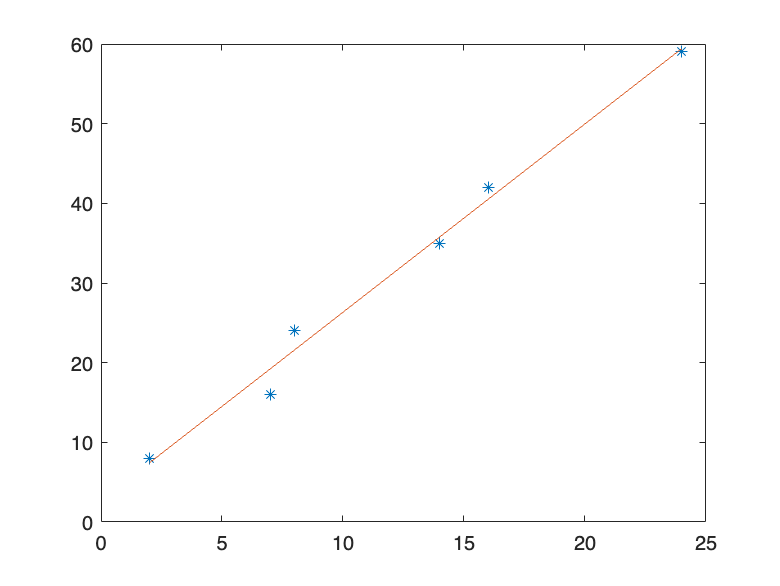

r2 = 0.9886

clear; clc;

x = [2 7 8 14 16 24];
y = [8 16 24 35 42 59];

r2 = min_cuad(x,y)

function r2 = min_cuad(x,y)
    n = numel(x);
    
    a = ((n*sum(x.*y)) - (sum(x)*sum(y))) / ((n*sum(x.^2) - sum(x)^2));
    b = (sum(y) - a*sum(x)) / (n);
    
    xP = sum(x) / numel(x);
    yP = sum(y) / numel(y);
    
    r = (sum((x-xP).*(y-yP))) / (sqrt(sum((x-xP).^2)) * sqrt(sum((y-yP).^2)));
    r2 = r^2;
    
    yy = a.*x + b;
    plot(x,y,'*',x,yy);
end